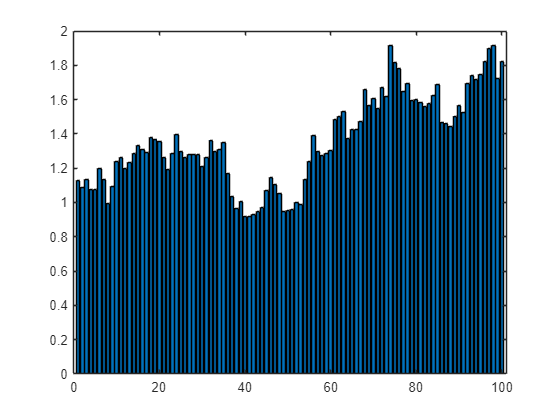

n = 512;

W = randn(n,n) * sqrt(2/(n+5));
W = randn(n,n);

iter = 100;
Z = zeros(n,iter);
variances_in_layers = zeros(1,iter);
mean_activation_in_layers = zeros(1,iter);
% bar_plt = bar(Z(:,1));
% ylim([-4,4])

x = randn(n,1);
z = x;

for i = 1:iter
    W = randn(n,n) * sqrt(1/n); % for standard normal distribution
    %W = (2*rand(n,n)-1) * sqrt(6./(2*n)); % for uniform initial distribution
    % W = 1*randn(n,n);

    z = W*z;
    
    % activation function
    % z = 1./(1 + exp(-z));
    % z(z<=0)=0; % ReLU
    
    var_of_Layer = var(z, 1);
    mean_activation = mean(z);
    % histogram(z);
    % pause(0);

    variances_in_layers(i) = var_of_Layer;
    mean_activation_in_layers(i) = mean_activation;
    
    % bar_plt.YData = z;
end

% m = mean(abs(Z), 2);
% s = var(Z, [], 1);



bar((variances_in_layers))

variances_in_layers(end)

ans = 1.8222

mean_activation_in_layers(end)

ans = -0.0286


fprintf(" Variance of activations in last layer: %s ", num2str(round(variances_in_layers(end), 2)));

 Variance of activations in last layer: 1.82 

fprintf(" Mean activation in last layer: %s ", num2str(round(mean_activation_in_layers(end), 2)));

 Mean activation in last layer: -0.03 


% mean(s)

% xlim([-4,4])
% ylim([-4,4])


%%% Test
% a = 10*randn(10000,1);
% b = 5*randn(10000,1);
% 
% c = a.*b;
% 
% sqrt(var(c, 1))